# MPEG Assignment 

### Introduction:

MPEG is an organization that develops standards for audio and video compression. It has created widely used formats like MPEG-1, MPEG-2, MPEG-4, and MPEG-7. These formats revolutionized digital media by enabling efficient storage, transmission, and playback of multimedia content. MPEG's standards have impacted broadcasting, streaming services, video conferencing, and digital storage, improving accessibility and quality of audiovisual content globally.

### MPEG implementation : 

**Layer I&II**  The basic technique of time to frequency mapping is to pass the signal through a bank of filters that parse the signal into K different bands of frequencies. And, this will be done in this part by calculating the Impulse Response of 32 Filter Bank , then passing the signal through these filters , after that all make a filtering for the signal and downsampling . 

 - Reading the Audio Signal , the Filter Coeffiicent , and assign the Audio signal into a variable :

%% Assigning the Path of audio file in a variable
   Audio_File =  "C:\Users\dell3510\Downloads\Music\listen-to-the-ancient-egyptions-tv.wav";
%% Reading the Audio File uisng audioread function
   [Audio,Sampling_Frequency] = audioread(Audio_File);
%% Assigning the Path of Filter File in a variable
   Filter_File ="C:\Users\dell3510\Downloads\CIE_442_COURSE_ASSIGNEMENT\filters.txt";


 - Reading the Filter Coefficients and make a mirror for the Filter Coefficients, to construct the 513 Filter Coefficients : 

%% Reading the Filter Coefficients in filter File && and make a copy of it reversed around the y-axis and concatenate it with the original one 
   Filter_Coefficient= dlmread(Filter_File);
   % Create a reflection of the filter coefficients around the y-axis
   Reflected_Coefficient = flipud(Filter_Coefficient);
   % Concatenate the original and reflected filter coefficients && and make sure that the size of filter coefficients is 513 
   New_Filter_Coefficient = [Filter_Coefficient;Reflected_Coefficient(2:end)];
   %Plotting the Filter Coefficients 
    figure(1);
    plot(New_Filter_Coefficient);
    title('New Filter Coefficients');
    xlabel('Sample Index');
    ylabel('Coefficient Value');

-Calculating the Impulse Response of 32 Filter bank using Equation in the Standard : 

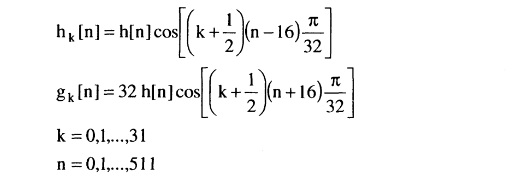

%% Calculate the impulse responses of the 32 filters
  % Define the number of SubBands
   Num_SBands = 32;
   % Define the Length of Filter
   Filter_Length = 512;
   % Initialize the array to store the impulse responses of analysis filters
   Impulse_Response = [];
   % Iterate over the filters and calculate the impulse response of each filter
   for k =0:1:Num_SBands-1
        % Initialize the vector to store the impulse response for each analysis filter
        Impulse_H_k = [];
        for n = 0:1:Filter_Length-1
            % Calculate the impulse response for H_k[n] 
            Impulse =New_Filter_Coefficient(n+1)*cos((k+0.5)*(n-16)*(pi/32));
            Impulse_H_k = [Impulse_H_k Impulse];
        end
        % Store the impulse responses in the matrix
        Impulse_Response = [Impulse_Response;Impulse_H_k];
   end

- Mapping to Spectral by Filtering the Audio signal using 32 Filter Bank :

 % Create an empty array for Filtered Signal
   Filtered_Signal = [];
   for k=0:Num_SBands-1
         % Applying each filter from the filter bank to the audio signal , and 1 represents that FIR filter that one will be used 
         Filtered_Signal(:,k+1) =filter(Impulse_Response(k+1,:), 1, Audio);
   end

- PLotting the Frequency spectrum of the Filtered Signal :

% Compute the FFT of the filtered signal
Fs = Sampling_Frequency;  % Sampling frequency
L = size(Filtered_Signal, 1);  % Length of the filtered signal
Y = abs(fft(Filtered_Signal))/L;
f = Fs*(0:(L/2))/L;

% Plot the frequency spectrum
plot(f, Y(1:L/2+1))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Frequency Spectrum of Filtered Signal')

- DownSampling the Filtered Signals of each Subband by a factor of 32 : 

%% Downsampling the filtered signals of each subband by a factor of 32
   % create an empty array for DownSampled_Signals 
   Downsampled_Signals =[];
   % Looping over each subpand and make the DownSampling 
   for k = 0:Num_SBands-1
       % Downsample each filtered signal by a factor of 32
       Downsampled_Signal(:,k+1) = downsample(Filtered_Signal(:,(k+1)),32);
   end
   %Appending the DownSampled_Signal in the Downsampled_Signals
   Downsampled_Signals=[Downsampled_Signals;Downsampled_Signal]

Downsampled_Signals =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0

**FFT Using Overlap and Add : **

-FFT using Overlap and Add techiniques is composed of dividing the Audio signal into N segments and Shift from one segment to another by adding M From the start of the Audio signals, and by windowing using Sine Signal : 

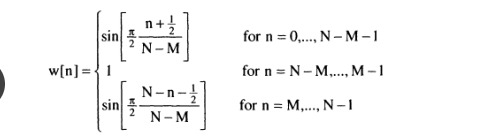

Then adding whole the output and apply N-point DFT across the segements while shifting :

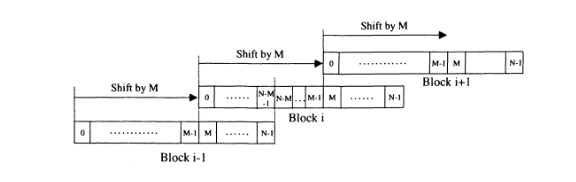

% Determine the block size and overlap
% N point FFT 
N = 1024;
% Range of M among 512 and 1024 
M = 512;   
% Overlap
overlap = N-M;
% Stop condition
if overlap > N/2
    error('Overlap must not be larger than N/2');
end
% Initialize the Sine window 
W_1 = zeros(N-M,1);
W_2 = ones(M-(N-M)+1,1);
W_3 = zeros(N-M,1);
for n = 0:(N-M-1)
    W_1(n+1) = sin(pi/2*((n+0.5)/(N-M)));
end
for n = M:(N-1)
    W_3(n+1-M+1) = sin(pi/2*((N-n-0.5)/(N-M)));
end
W = [W_1; W_2; W_3];
% Applying windowing and overlap-and-add
Output = zeros(size(Audio));
for i = 1:M:length(Audio) - N
    % Extract current segment from the audio signal
    Block = Audio(i:i+N-1);
    % Windowing
    Windowed_Block = Block .* W;
    % Fourier Transform
    Frequency_Components = fft(Windowed_Block, N);
    % Quantization
    Quantized_Components = round(Frequency_Components);
    % Dequantization
    Dequantized_Components = Quantized_Components;
    % Inverse Fourier Transform
    Reconstructed_Block = ifft(Dequantized_Components);
    % Windowing and Overlap-and-Add
    Output(i:i+N-1) = Output(i:i+N-1)+ Reconstructed_Block.* W;
end
% Write the output audio to a file
output_file = 'output_audio.wav';
audiowrite(output_file, Output, sampling_frequency);

**Layer_III**

**Psychoacoustic Model 1** This Part will involve the seperation among audioable Tones and nonaudioabl , and classifiy whethere the tones is Tonal or not Tonal .  

** Audioable and nonaudioable Part **: 

-Reading the Signal spectrum, and computing the sound pressure levels or Lks using Equation : 

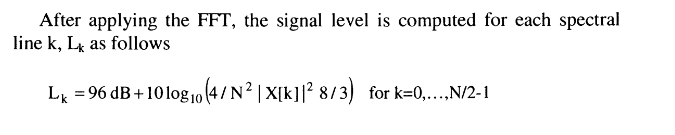

   % Loading the Signal_Spectrum L[k] using the given X[k]
   load("C:\Users\dell3510\Downloads\CIE_442_COURSE_ASSIGNEMENT\Signal_Spectrum.mat",'Signal_Spectrum');
   % Computing SPL L_K[k] using X[k]
   % Length of SPL Line
   N = 1024; 
   % Half length of SPL Line
   N_Half = N/2; 
   % Initialize the array for sound pressure levels
   Sound_Pressure_Level = zeros(1, N_Half); 
   % Computating the Sound Pressure level 
   for k = 0:(N_Half-1)
       %using the Equation from the text Book ,To calculate the SPL and
       %make a shift for each value in the Signal spectrum by 512 to make
       %deal with time delay among Filter Bank and the input to the model 
        Sound_Pressure_Level(k+1) = 96+10*log10(4/((N*N)*(abs(Signal_Spectrum(k+1+512))^(2))*(8/3)));
   end


-Calculating threshold in Quit_A  : 

%% Calculate Quit_A
    % Initialize the list for Quit_A
    Quit_A = zeros(1, length(Sound_Pressure_Level));
    % Initializing Frequency Vector 
    Freq=linspace(0,Sampling_Frequency/2,512);
    % Computating Quit_A
    for k = 1:length(Freq)
        Quit_A(k) =(3.64*((Freq(k)/1000)^(-0.8)))-(6.5*exp(-0.6*((Freq(k)/1000)-3.3)^(2)))+(10^(-3))*((Freq(k)/1000)^(4));
        
    end
    %% Plotting Quit_A 
        figure(2);
        plot(Freq, Quit_A);
        xlabel('Frequency (Hz)');
        ylabel('Quit_A');
        title('Quit_A versus Frequency');

-Comparing each SPL with Quit _A thershold to determine , whether it is audioable or not , if it is less than Quit_A thershold we make it zero :

 %Comparing each SPL with Quit_A and make it Zero if it is less than Quit_A
 %thershold
 for k = 1:length(Sound_Pressure_Level)
        if Sound_Pressure_Level(k) < Quit_A(k)
            Sound_Pressure_Level(k) = 0;
        end
 end

**Tonal and nonTonal Part** : 

-Dividing the Spectrum of the Signal into 32 SubBand : 

%% Dividing the Signal spectrum of the Frequency domain of the signal into 32 subbands 
    % Make a transpose for Sound Pressure Levels 
    Sound_Pressure_Level= transpose(Sound_Pressure_Level);
    % Define the number of sub-bands
    Num_Of_Sub_Bands= 32;
    % Calculate the number of frequency points per sub-band
    Sub_Band_length = floor(length(Sound_Pressure_Level)/Num_Of_Sub_Bands);
    % Initialize a matrix to store the sub-band representations
    Sound_Pressure_Levels_Bands = zeros(Num_Of_Sub_Bands,Sub_Band_length); 
    % Iterate over the sub-bands
    for i = 1:Num_Of_Sub_Bands
          % Calculate the start indecies for the current subband 
          Start_Index =(i-1)*Sub_Band_length+1;
          % Calculate the end indecies for the current subband
          End_Index =i*Sub_Band_length;
          % Extract the Sound Pressure levels values for the current sub-band
          Sound_Pressure_Levels_Bands(i,:) = Sound_Pressure_Level(Start_Index:End_Index);
    end

-Dividing the Frequency into 32 Subband of Frequencies : 

%% Dividing the Signal spectrum of the Frequency domain of the signal into 32 subbands 
    % Make a transpose for Frequency Bands  
    Freq= transpose(Freq);
    % Define the number of sub-bands
    Num_Of_Sub_Bands= 32;
    % Calculate the number of frequency points per sub-band
    Sub_Band_length = floor(length(Freq)/Num_Of_Sub_Bands);
    % Initialize a matrix to store the sub-band representations
    Freq_Bands= zeros(Num_Of_Sub_Bands,Sub_Band_length); 
    % Iterate over the sub-bands
    for i = 1:Num_Of_Sub_Bands
          % Calculate the start indecies for the current subband 
          Start_Index =(i-1)*Sub_Band_length+1;
          % Calculate the end indecies for the current subband
          End_Index =i*Sub_Band_length;
          % Extract the Sound Pressure levelsvalues for the current sub-band
          Freq_Bands(i,:) = Freq(Start_Index:End_Index);
    end

-Determining the tonal maskers for each subband by locationg indices of the local maximas of each subband and Global maximas and their Values , in which the indecies represents the Frequencies : 

%Locating the Maximum Sound Pressure level in each SubBand and the Local
%maximas in each one & and their Correspending frequencies  
Sound_Pressure_Levels_Bands=reshape(Sound_Pressure_Level,32,16);  %reshapes the Sound_Pressure_Level matrix into a 32x16 matrix, representing the sound pressure levels in different frequency bands.
Freq_Bands=reshape(Freq,32,16);  %reshapes the Freq matrix into a 32x16 matrix, representing the corresponding frequencies for each subband.
for w = 1:16
    % Getting each Sub_Band from the Sound pressure levels bands 
    Sound_Pressure_Levels_Sub_Bands=Sound_Pressure_Levels_Bands(:,w);
    % Getting each Sub_Band from Frequency bands 
    Freq_Sub_Bands=Freq_Bands(:,w);
    % Finding the Global maximum in each subband from the Sound pressureLevels 
    [Max_Sub_Band, c] = max(Sound_Pressure_Levels_Sub_Bands);
    %Finding the Local Maximum in each sub Band and their Correspending frequencies 
    [values, Loca] = findpeaks(Sound_Pressure_Levels_Sub_Bands,Freq_Sub_Bands);
    %Concatenating the Maximum Sound Pressure level and their indecies 
    values = [values;Max_Sub_Band];
    %Concatenating the Local Maxima and their indecies 
    Freq_Values = [Loca;Freq_Sub_Bands(c)];
    % to apply masking to involved maskees
    for i = 1:length(values)
        Sound_Pressure_Level_1 = values(i); %assign the current sound pressure level.
        Frequency_Values= Freq_Values(i);   %assigns the corresponding frequency.
        % to use the masker if its SPL is larger than 0 dB
        if Sound_Pressure_Level_1 > 0
            % Find the rightmost frequency affected by the masker and By that the Range of Frequenciue that will be affected By the Masker will be determined 
            Frequency_Range = masking_threshold(Sound_Pressure_Level_1,Frequency_Values);
            % to calculate the corresponding minimum audible SPL (threshold of quiet value)
            Sound_Pressure_Level_2 = threshold_quiet(Frequency_Range);
            % Interpolate the Thershold 
            coff=polyfit([Frequency_Values Frequency_Range],[Sound_Pressure_Level_1 Sound_Pressure_Level_2],1); 
            % Multiplying the Coefficient with delta which equals 1.5
            coff= 1.5*coff(1);
            % Construct/interpolate a straight line representing the masking threshold
            % for frequencies around the masker
            for j = 1:length(Freq_Sub_Bands)
                if Freq_Sub_Bands(j) < Frequency_Range && Freq_Sub_Bands(j) > Frequency_Values; %check if the current frequency falls within the range of frequencies affected by the masker.
                    % interpolation to calculate the sound pressure level threshold for the current frequency.
                    Sound_Pressure_Level_Freq_in_Between=polyval(coff,Freq_Sub_Bands(j));
                    %calculates the threshold of quiet value for the current frequency.
                    A_freq_in_between=threshold_quiet(Freq_Sub_Bands(j));
                    if Sound_Pressure_Level_Freq_in_Between< A_freq_in_between 
                        Sound_Pressure_Levels_Bands(j,w)=0;  %set the sound pressure level in the original matrix to 0, indicating that it is masked.
                    end
                end
            end
        end
    end
end
Sound_Pressure_Levels_Bands=reshape(Sound_Pressure_Levels_Bands,512,1)

Sound_Pressure_Levels_Bands =          0
         0
         0
         0
         0
         0
         0
   19.6013
   23.9846
         0


    %%Plotting the Freq_Sub_Bands
    plot(Freq,Sound_Pressure_Levels_Bands);
    title("freq of spectrum");
    xlabel("freq");
    ylabel("Sound_Pressure_Levels(DB)");

## **Encoding Process:**

-Taking Fast fourier transform for each subband  from the output of the 32 Filter Banks  , and then compute the associated SPL values for each subband:

    % Constants  
    Num_Sub_Bands = 32;
    N_FFT = 1024;
    FFT_Range = 513:1024;
    % Inilization arrays for FFT of Filter ,SPL and Frequencies 
    FFT_Filter= zeros(Num_Sub_Bands,N_FFT);
    SPL_Filter = zeros(Num_Sub_Bands, 512);
    Frequencies = zeros(Num_Sub_Bands, 512);
    % Applying FFT on the filter output
    for k = 1:Num_Sub_Bands
        FFT_Filter(k, :) = fft(Downsampled_Signals(k, :),N_FFT);
    % Calculating SPLs for the filtered signal 
        SPL_Filter(k, :) = 96+10*log10((4/((N_FFT)^2)*abs(FFT_Filter(k,FFT_Range)).^(2)*(8/3)));
    % Multiplying the Lk-->(Sound_Pressure_Level) vector by the filter SPLs
        Frequencies(k, :) = Sound_Pressure_Level'.*SPL_Filter(k, :);
    end
    % Addition of Results resultant SPLs
    Sum_SPL = sum(Frequencies,2)';

### Bit allocation

- Determining the number of bits to allocate for each subband based on the maximum SPL value

    
subband_bits = zeros(1,32);

BPS_signal=audioinfo(Audio_File).BitsPerSample

BPS_signal = 16

count = 0;
if BPS_signal<=16
    BPS = BPS_signal;
else
    BPS = 16;
end

b = BPS;

for i=1:1:32
    [smax,index] = max(Sum_SPL);
    index;
    
    if count < 4
        b = BPS;
    elseif count<8
        if BPS - 10 >= 2 
            b = BPS - 10;
        else
            b = 2;
        end
    elseif count<12
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<16
        if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
        end
    elseif count<20
       if BPS - 14 >= 2
            b = BPS - 14;
        else
            b = 2;
       end
    elseif count<24
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 2;
        end
    elseif count<28
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    else
        if BPS - 15 >= 1
            b = BPS - 15;
        else
            b = 1;
        end
    end
    subband_bits(index) = b;
    count = count + 1;
    sum_spl(index) = -inf;
end


#### Filter Bank:

- Using the filter function, the code applies each filter from the filter bank to the audio stream. The Filtered_Signal1 matrix stores the output signals.

- The filtered signals are then downsampled by a factor of 32 with the downsample function and saved in the filter_for_encoding_signal matrix.

Filtered_Signal1 = []; % Initialization an empty matrix that will store the filtered signals for each subband.

filter_for_encoding_signal=[];   % Initialization an empty matrix that will store the downsampled filtered signals for each subband.

   for k=0:31
         % to apply each filter from the filter bank to the audio signal , and 1 represents that FIR filter that one will be used 
         Filtered_Signal1(k+1,:) =filter(Impulse_Response(k+1,:), 1, Audio);
         filter_for_encoding_signal(k+1,:)= downsample(Filtered_Signal1(k+1,:),32);
   end


### **Quantization:**

- The goal of quantization in this code is to lower the accuracy of the signal values in each frame, decreasing data size while introducing some quantization error.

- Quantization is applied to the frames of signals stored in the `filter_for_encoding_signal` matrix. 

- The code iterates over each frame and extracts 12 elements from each frame. 

- These elements are then passed to the `Quan` function for quantization.

- The `Quan` function determines the maximum and minimum values of the extracted elements and performs quantization on them based on the corresponding `subband_bits` value.

sampled_quantization_values= []; % to initialize  an empty vector that will store the quantized values for each frame.
num_frames = size(filter_for_encoding_signal, 2) / 12; % the number of frames is calculated as the number of columns in filter_for_encoding_signal divided by 12, representing the number of frames.

frames = zeros(num_frames, 384); % to initialize a matrix with num_frames rows and 384 columns, where each row represents a frame.

minimum_array = [];      %%  initialize an array to store minimum values
maximum_array = [];      %%  initialize an array to store maximum values

for i = 1:size(filter_for_encoding_signal, 1) % iterates over the rows of the filter_for_encoding_signal matrix. it extracts 12 elements from the current row of the frame.

    for j = 1:12:size(filter_for_encoding_signal, 2) % a loop that iterates over the columns of the filter_for_encoding_signal matrix
        
        if j+11 <= size(filter_for_encoding_signal, 2)

            
   
                % to extract 12 elements from the current row
                current_elements_fromrow = filter_for_encoding_signal(i, j:j+11);

                [maximum_value, minimum_value, sampled_quantization_value] = Quan(current_elements_fromrow, subband_bits(i));  %extracted elements and the corresponding subband_bits value for quantization,

                sampled_quantization_values = [sampled_quantization_values, sampled_quantization_value];    %% quantized value is appended to the sampled_quantization_values 

                maximum_array = [maximum_array, maximum_value];       %% maximum value is appended to the maximum_array
                minimum_array = [minimum_array, minimum_value];       %% minimum value is appended to the minimum_array
        end
    end
    
  
end

## Decoder

#### 1- De-quantization

The decoder restores the quantized spectral components of the signal by decoding the samples of each subband as follows:

- Number of bits used in quantizing the subband is obtained from the encoded signal.

- Maximum value and  Minimum value are used in quantizing the subband is obtained from the encoded signal.

- Quantized Levels of the subband is obtained from the encoded signal.


% Transforming the 1D array into Matrix ( 625 (number of frames) X 384 (12 samples from each 32 subband) )
length_quantized = length(sampled_quantization_values);
num_of_values = 12*32;
Num_of_frames = length_quantized/num_of_values;

reshaped_array = reshape(sampled_quantization_values,Num_of_frames,num_of_values); 

% reshaping the minmum and maximum arrays
num_of_col_values = 32;
reshaped_max_array = reshape(maximum_array,Num_of_frames,num_of_col_values);
reshaped_min_array = reshape(minimum_array,Num_of_frames,num_of_col_values);

### Deuantization

counter = 1; % to loop over the 32 values
dequantized=[];
dequantized_signal=[];
 

for frame = 1: Num_of_frames % to loop over 625 frame
    for band = 1:12:num_of_values % taking the 32 subband by dequantizing 12 samples each time
        if band+11 < num_of_values % to check over the border condition
            if counter <= 32 % to avoid exceeding the 32 subbands
                quan = reshaped_array(frame,band:band+11);
                disp(quan)
                dequantized = DeQuan(reshaped_max_array(frame,counter),reshaped_min_array(frame,counter),subband_bits(counter),quan);
                dequantized_signal = [dequantized_signal;dequantized];
                counter = counter + 1; % to increase each subband
            else
                % to return to the fist element if the 32 had finished
                counter = 1;
            end
        end
    end
end
dequantized_signal = reshape(dequantized_signal', 1, []);

2- Synthesis Filter "Frequency-to-Time mapping": 

 Reconstructing the time-domain representation of the audio signal from its frequency representation.

- Data is up-sampled by a factor of 32 prior to recombining the sub-band signals to get back to the original data rate.View instructions

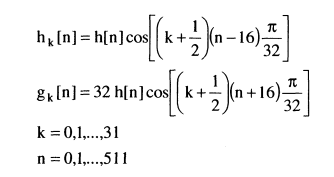

%% Synthesizer

g = [32,512];
% Defining the coffecients that would be used
for k=0:31
    for n=0:511
        g(k+1,n+1) = 32 * New_Filter_Coefficient(n+1) * cos((k+1/2) * (n+16) * (pi/32) );
    end
end

upsampled_signal = [];
reconstructed_signal = [1,240000];
% upsambling the dequantized signal with factor 32
upsampled_signal(1:end) = upsample(dequantized_signal(1:end),32);
% reconstruct the signal
reconstructed_signal(1:end) = New_Filter_Coefficient(g(11,:),1,upsampled_signal(1,:));

